# Matias Hiillos 268285

close all
clear all

x = 0:0.05:2*pi;

x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


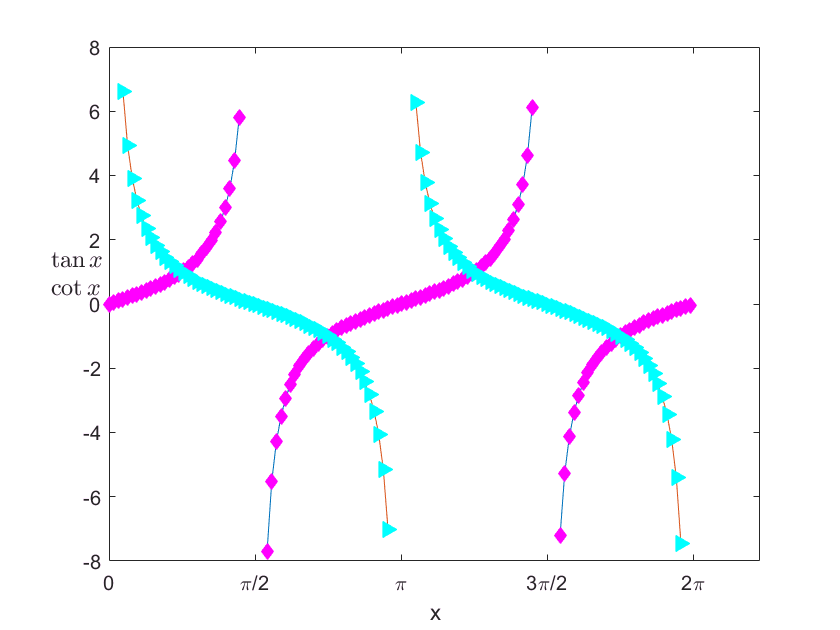

plot_handle_tan = plot(x,tan(x));
hold on
plot_handle_cot = plot(x,cot(x));

for i = 1: length(x)
    if abs(plot_handle_tan.YData(i)) > 8
        plot_handle_tan.YData(i) = NaN;
    end
    
    if abs(plot_handle_cot.YData(i)) > 8
        plot_handle_cot.YData(i) = NaN;
    end
end

tickmarks = [ 0 pi/2 pi 3*pi/2 2*pi ];
axis = gca;

axis.XTick = tickmarks;
axis.XTickLabel = {'0','\pi/2','\pi','3\pi/2','2\pi'};

xlabel('x')
ylabel({'$\tan x$','$\cot x$'},'Interpreter','latex','FontSize',12,'Rotation',0)

plot_handle_tan.Marker = 'diamond';
plot_handle_tan.MarkerFaceColor = 'magenta';
plot_handle_tan.MarkerEdgeColor = 'magenta';
plot_handle_tan.MarkerSize = 6;

plot_handle_cot.Marker = '>';
plot_handle_cot.MarkerFaceColor = 'cyan';
plot_handle_cot.MarkerEdgeColor = 'cyan';
plot_handle_cot.MarkerSize = 7;